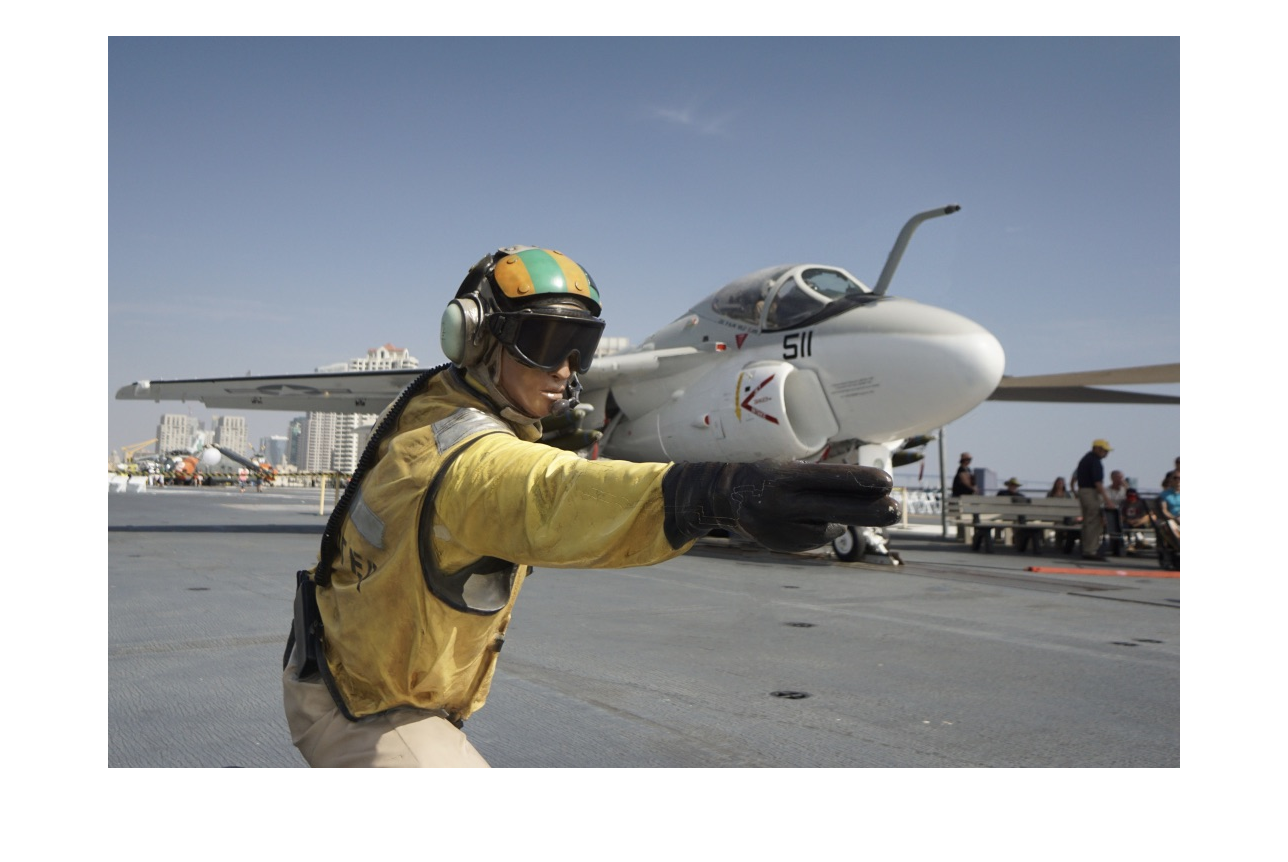

%convert the image to YUV type
[pilot] = imread('pilot.tiff');
[key] = imread('baseball.tiff');

[row,col,channel]=size(pilot);
key = imresize(key,[row,col]);

imshow(pilot);


s=rng;
noise = rand(8,8);
noise(8,8)=0;

%YUV should be value in [0,255]
pilot_YUV=rgb2ycbcr(pilot);
key_YUV = rgb2ycbcr(key);

key_dct=zeros(row,col,channel);
RLencode={[],[],[]};
DC_matrix={[],[],[]};

quatization_matrix=[
[1,1,1,1,1,1,1,1]
[1,1,1,1,1,1,1,1]
[1,1,1,1,1,1,1,1]
[1,1,1,1,1,1,1,1]
[1,1,1,1,1,1,1,1]
[1,1,1,1,1,1,1,1]
[1,1,1,1,1,1,1,1]
[1,1,1,1,1,1,1,99]];

% slice each part into 8*8 matrix, do dct,quantization,encode
for i=1:row/8
    for j=1:col/8
        for k=1:channel
            downsample_pilot=pilot_YUV(8*i-7:8*i,8*j-7:8*j,k);
            downsample_key = key_YUV(8*i-7:8*i,8*j-7:8*j,k);
            % for each 8*8 input matrix apply dct
            key_dct(8*i-7:8*i,8*j-7:8*j,k) = dct2(downsample_key);
            pilot_dct=dct2(downsample_pilot)*0.1+key_dct(8*i-7:8*i,8*j-7:8*j,k)*0.9;
            %divide by quantization matrix
            pilot_qua=round(pilot_dct./quatization_matrix+noise);
            %zigzag & Run length encode
            [DC,pilot_encode,code]=encode_vertical(pilot_qua);
            % for each channel, run length encode link into a vector, store each DC term in another array 
            DC_matrix{k}=[DC_matrix{k},DC];
            RLencode{k}=[RLencode{k},code];
        end
    end
end

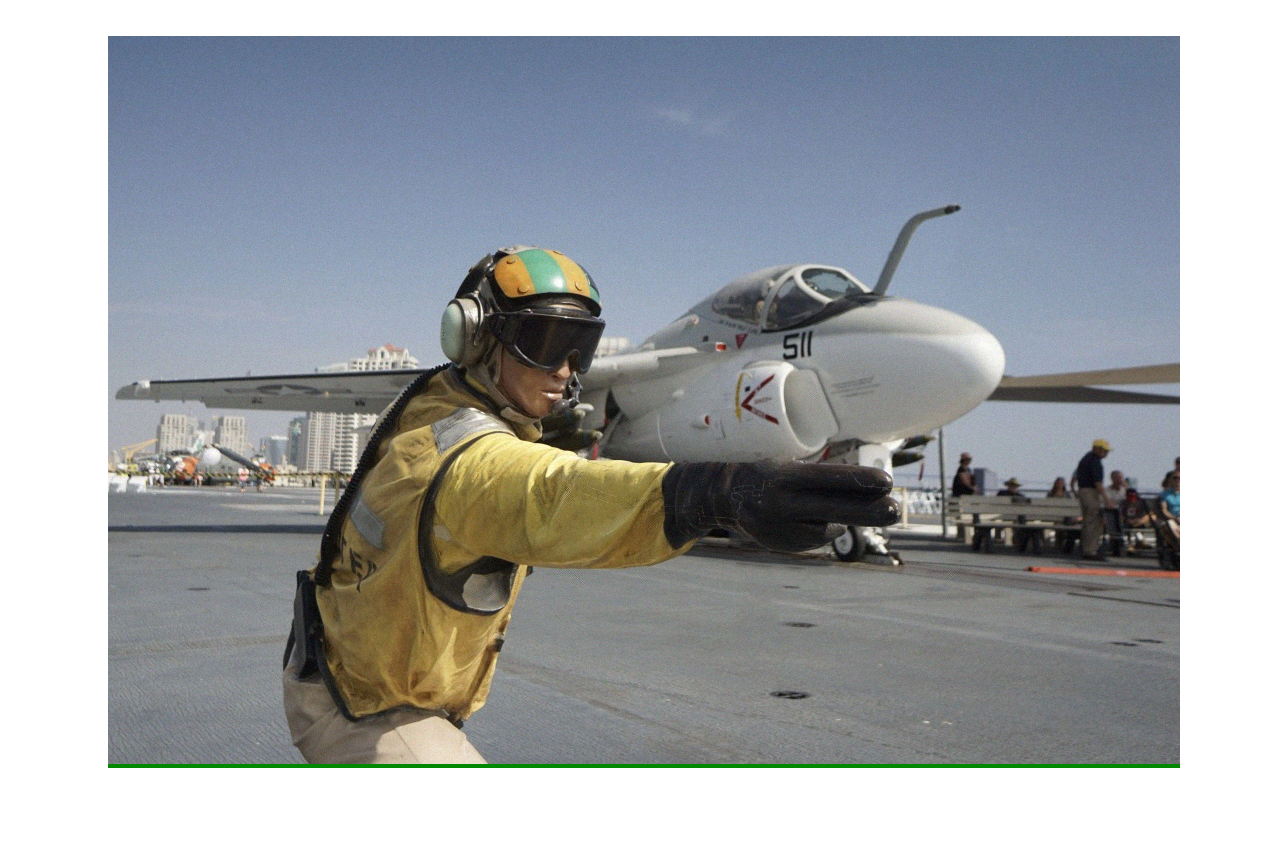

DC_cell = [];
AC_cell = [];
recover_decode = zeros(row,col,channel);
recover_quantization = zeros(row,col,channel);
recover_dct = zeros(row,col,channel);

for k=1:channel
    DC_cell = DC_matrix{k};
    AC_cell = RLencode{k};
    for i=1:row/8
        for j = 1:col/8
            if ~isempty(DC_cell) && ~isempty(AC_cell)
                % Extract RLcode of single 8*8 matrix
                [AC,AC_cell] = crop_AC (AC_cell);
                decode_temp = decode_vertical(DC_cell(1),AC);
                % Delete DC term
                DC_cell(1)=[];
                % Store the 8*8 matrix 
                recover_decode(8*i-7:8*i,8*j-7:8*j,k) = decode_temp;
                % Dequantized the matrix
                decode_temp = (decode_temp-noise) .* quatization_matrix;
                recover_quantization(8*i-7:8*i,8*j-7:8*j,k)=decode_temp;
                decode_temp = (decode_temp - 0.9*key_dct(8*i-7:8*i,8*j-7:8*j,k))*10;
                recover_dct(8*i-7:8*i,8*j-7:8*j,k) = idct2(decode_temp);
            end
        end
    end
end

recover_dct = uint8(recover_dct);
recover_pilot=ycbcr2rgb(recover_dct);

imshow(recover_pilot);